# **RS-WISP-08-11: Safety Ellipse in  Approaching Sequence**

**WorkerInSpace**

**Hongseok Kim**

**2025/07/21**

clear;clc;
0.1/180*pi*(36000+6378)

ans = 73.9636

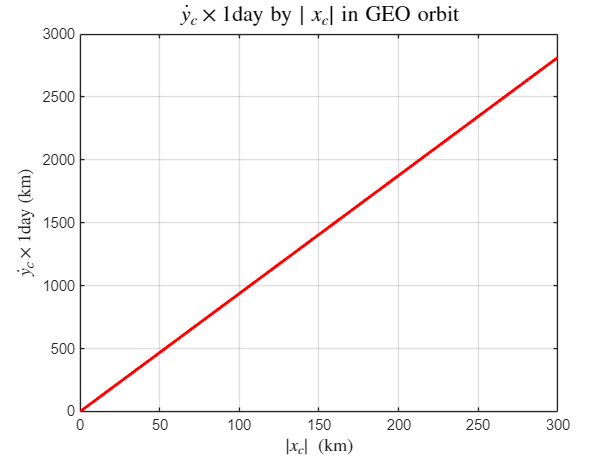

mu = 398600.4415;
a_target = 6378 + 36000;

n_target = sqrt(mu/a_target^3);

x_c_data = linspace(0,300);
y_c_dot_data = 3*n_target/2*3600*24*x_c_data;

figure(1);
plot(x_c_data, y_c_dot_data,'r','LineWidth',2)
xlabel('$\left|x_c \right|\;\;\left(\mathrm{km}\right)$','Interpreter','latex','FontSize',12)
ylabel('${\dot{y} }_c \times 1\mathrm{day}\;\left(\mathrm{km}\right)$','Interpreter','latex','FontSize',12)
title('${\dot{y} }_c \times 1\mathrm{day}\;\mathrm{by}\;\left|\;x_c \right|\;\mathrm{in}\;\mathrm{GEO}\;\mathrm{orbit}$','Interpreter','latex','FontSize',15)
grid on


3*n_target/2*3600*24

ans = 9.3791

  figure;
   hold on
   grid on

x_lvlh_0 = -6;
y_lvlh_0 = -149.65;
z_lvlh_0 = 0;
n = n_target;

x_0 = x_lvlh_0;
y_0 = y_lvlh_0;
z_0 = z_lvlh_0;

x_c = -5;
x_max = 1;
z_max = 0;
% Get first manuver relative velocity
[x_dot_0, y_dot_0, z_dot_0, x_c, y_c, y_dot_c, alpha, beta] = get_relative_vel_from_SE(x_0, y_0, z_0, x_c, x_max, z_max, n);
number_of_periods = 0.5;
% Drow the Trajectory
[x_t, y_t] = drowing_trajectory(number_of_periods, x_max, z_max, x_c, y_c, y_dot_c, alpha, beta, n);


% 2. Second Maneuver
x_0 = x_t(end);
y_0 = y_t(end);
x_c = -3;
% Get first manuver relative velocity
[x_dot_0, y_dot_0, z_dot_0, x_c, y_c, y_dot_c, alpha, beta] = get_relative_vel_from_SE(x_0, y_0, z_0, x_c, x_max, z_max, n);
number_of_periods = 2.5;
% Drow the Trajectory
[x_t, y_t] = drowing_trajectory(number_of_periods, x_max, z_max, x_c, y_c, y_dot_c, alpha, beta, n);


% 3. Third Maneuver
x_0 = x_t(end);
y_0 = y_t(end);
x_c = -1;
% Get first manuver relative velocity
[x_dot_0, y_dot_0, z_dot_0, x_c, y_c, y_dot_c, alpha, beta] = get_relative_vel_from_SE(x_0, y_0, z_0, x_c, x_max, z_max, n);
number_of_periods = 2.5;
% Drow the Trajectory
[x_t, y_t] = drowing_trajectory(number_of_periods, x_max, z_max, x_c, y_c, y_dot_c, alpha, beta, n);

% 4. 4th Maneuver
x_0 = x_t(end);
y_0 = y_t(end);
x_c = -0.8;
x_max = 0.8;
% Get first manuver relative velocity
[x_dot_0, y_dot_0, z_dot_0, x_c, y_c, y_dot_c, alpha, beta] = get_relative_vel_from_SE(x_0, y_0, z_0, x_c, x_max, z_max, n);
number_of_periods = 3;
% Drow the Trajectory
[x_t, y_t] = drowing_trajectory(number_of_periods, x_max, z_max, x_c, y_c, y_dot_c, alpha, beta, n)

x_t =    -0.0000   -0.0145   -0.0573   -0.1270   -0.2210   -0.3360   -0.4677   -0.6114   -0.7619   -0.9139   -1.0617   -1.2000   -1.3239   -1.4288   -1.5111   -1.5676   -1.5964   -1.5964   -1.5676   -1.5111   -1.4288   -1.3239   -1.2000   -1.0617   -0.9139   -0.7619   -0.6114   -0.4677   -0.3360   -0.2210   -0.1270   -0.0573   -0.0145   -0.0000   -0.0145   -0.0573   -0.1270   -0.2210   -0.3360   -0.4677   -0.6114   -0.7619   -0.9139   -1.0617   -1.2000   -1.3239   -1.4288   -1.5111   -1.5676   -1.5964


y_t =   -31.8403  -31.9146  -31.9780  -32.0199  -32.0305  -32.0012  -31.9248  -31.7958  -31.6106  -31.3677  -31.0675  -30.7126  -30.3077  -29.8591  -29.3747  -28.8639  -28.3367  -27.8040  -27.2769  -26.7660  -26.2816  -25.8330  -25.4281  -25.0732  -24.7731  -24.5301  -24.3449  -24.2159  -24.1395  -24.1102  -24.1209  -24.1628  -24.2261  -24.3005  -24.3748  -24.4382  -24.4800  -24.4907  -24.4614  -24.3850  -24.2560  -24.0708  -23.8279  -23.5277  -23.1728  -22.7679  -22.3193  -21.8349  -21.3240  -20.7969




% 5. 5th Maneuver
x_0 = x_t(end);
y_0 = y_t(end);
x_c = -0.6;
x_max = 0.6;
% Get first manuver relative velocity
[x_dot_0, y_dot_0, z_dot_0, x_c, y_c, y_dot_c, alpha, beta] = get_relative_vel_from_SE(x_0, y_0, z_0, x_c, x_max, z_max, n);
number_of_periods = 1;
% Drow the Trajectory
[x_t, y_t] = drowing_trajectory(number_of_periods, x_max, z_max, x_c, y_c, y_dot_c, alpha, beta, n)

x_t =    -0.0000   -0.0012   -0.0048   -0.0108   -0.0192   -0.0300   -0.0430   -0.0582   -0.0757   -0.0952   -0.1168   -0.1404   -0.1658   -0.1929   -0.2217   -0.2520   -0.2837   -0.3166   -0.3508   -0.3859   -0.4218   -0.4585   -0.4958   -0.5335   -0.5715   -0.6095   -0.6476   -0.6854   -0.7229   -0.7599   -0.7962   -0.8318   -0.8664   -0.9000   -0.9324   -0.9634   -0.9929   -1.0209   -1.0472   -1.0716   -1.0942   -1.1148   -1.1333   -1.1497   -1.1638   -1.1757   -1.1853   -1.1925   -1.1973   -1.1997


y_t =    -9.2208   -9.2398   -9.2585   -9.2766   -9.2937   -9.3096   -9.3241   -9.3367   -9.3473   -9.3555   -9.3611   -9.3638   -9.3635   -9.3598   -9.3525   -9.3415   -9.3266   -9.3075   -9.2842   -9.2565   -9.2243   -9.1875   -9.1459   -9.0997   -9.0486   -8.9927   -8.9319   -8.8664   -8.7960   -8.7209   -8.6412   -8.5569   -8.4682   -8.3751   -8.2778   -8.1765   -8.0714   -7.9626   -7.8504   -7.7349   -7.6165   -7.4953   -7.3716   -7.2458   -7.1180   -6.9885   -6.8577   -6.7258   -6.5931   -6.4600





% 6. 6th Maneuver
x_0 = x_t(end);
y_0 = y_t(end);
x_c = -0.25;
x_max = 0.25;
% Get first manuver relative velocity
[x_dot_0, y_dot_0, z_dot_0, x_c, y_c, y_dot_c, alpha, beta] = get_relative_vel_from_SE(x_0, y_0, z_0, x_c, x_max, z_max, n);
number_of_periods = 1.5;
% Drow the Trajectory
[x_t, y_t] = drowing_trajectory(number_of_periods, x_max, z_max, x_c, y_c, y_dot_c, alpha, beta, n)

x_t =    -0.0000   -0.0011   -0.0045   -0.0101   -0.0179   -0.0278   -0.0397   -0.0535   -0.0691   -0.0863   -0.1050   -0.1250   -0.1461   -0.1682   -0.1911   -0.2144   -0.2381   -0.2619   -0.2856   -0.3089   -0.3318   -0.3539   -0.3750   -0.3950   -0.4137   -0.4309   -0.4465   -0.4603   -0.4722   -0.4821   -0.4899   -0.4955   -0.4989   -0.5000   -0.4989   -0.4955   -0.4899   -0.4821   -0.4722   -0.4603   -0.4465   -0.4309   -0.4137   -0.3950   -0.3750   -0.3539   -0.3318   -0.3089   -0.2856   -0.2619


y_t =    -3.5659   -3.5778   -3.5892   -3.5997   -3.6090   -3.6166   -3.6221   -3.6251   -3.6254   -3.6225   -3.6162   -3.6063   -3.5924   -3.5743   -3.5520   -3.5254   -3.4942   -3.4585   -3.4183   -3.3735   -3.3244   -3.2711   -3.2136   -3.1521   -3.0870   -3.0185   -2.9468   -2.8724   -2.7955   -2.7165   -2.6358   -2.5539   -2.4711   -2.3878   -2.3046   -2.2218   -2.1399   -2.0592   -1.9802   -1.9033   -1.8289   -1.7572   -1.6887   -1.6236   -1.5621   -1.5046   -1.4512   -1.4021   -1.3574   -1.3172




% 7. 7th Maneuver
x_0 = x_t(end);
y_0 = y_t(end);
x_c = 0;
x_max = 0.5;
% Get first manuver relative velocity
[x_dot_0, y_dot_0, z_dot_0, x_c, y_c, y_dot_c, alpha, beta] = get_relative_vel_from_SE(x_0, y_0, z_0, x_c, x_max, z_max, n);
number_of_periods = 1.5;
% Drow the Trajectory
[x_t, y_t] = drowing_trajectory(number_of_periods, x_max, z_max, x_c, y_c, y_dot_c, alpha, beta, n)

x_t =    -0.5000   -0.4977   -0.4910   -0.4797   -0.4642   -0.4444   -0.4206   -0.3930   -0.3619   -0.3274   -0.2900   -0.2500   -0.2077   -0.1635   -0.1179   -0.0712   -0.0238    0.0238    0.0712    0.1179    0.1635    0.2077    0.2500    0.2900    0.3274    0.3619    0.3930    0.4206    0.4444    0.4642    0.4797    0.4910    0.4977    0.5000    0.4977    0.4910    0.4797    0.4642    0.4444    0.4206    0.3930    0.3619    0.3274    0.2900    0.2500    0.2077    0.1635    0.1179    0.0712    0.0238


y_t =    -0.0316    0.0634    0.1576    0.2501    0.3400    0.4266    0.5090    0.5865    0.6584    0.7241    0.7829    0.8344    0.8780    0.9134    0.9402    0.9582    0.9672    0.9672    0.9582    0.9402    0.9134    0.8780    0.8344    0.7829    0.7241    0.6584    0.5865    0.5090    0.4266    0.3400    0.2501    0.1576    0.0634   -0.0316   -0.1267   -0.2209   -0.3134   -0.4033   -0.4899   -0.5723   -0.6498   -0.7217   -0.7874   -0.8462   -0.8977   -0.9413   -0.9767   -1.0035   -1.0215   -1.0305


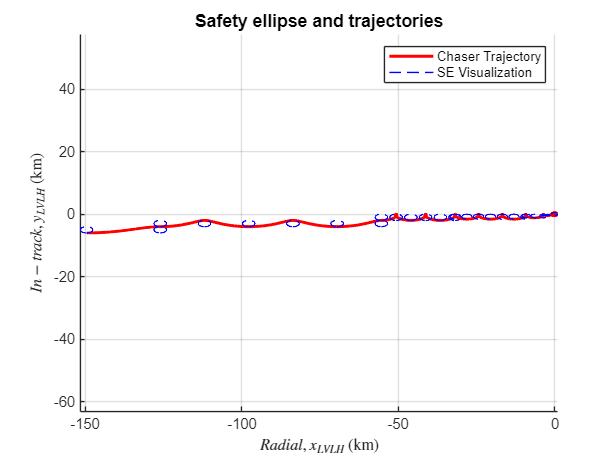



axis('equal')
xlabel( '$Radial, x_{LVLH}$ (km)', 'Interpreter', 'latex')
ylabel('$In-track, y_{LVLH}$ (km)', 'Interpreter', 'latex')
title('Safety ellipse and trajectories','FontSize',12,'FontWeight','bold')
legend('Chaser Trajectory','SE Visualization')

## III.3 Function for get safety ellipse parmeters

function [x_dot_0, y_dot_0, z_dot_0, x_c, y_c, y_dot_c, alpha, beta] = get_relative_vel_from_SE(x_0, y_0, z_0, x_c, x_max, z_max, n)

   y_dot_c = -3/2*n*x_c;
   y_dot_0 = -1/3*y_dot_c - 2*n*x_0;

   x_dot_0 = 0;
   y_c = y_0;
   z_dot_0 = 0;


  cos_alpha = -1/x_max * (3*x_0 +2*y_dot_0/n);
  sin_alpha = -1/x_max * (x_dot_0/n);

  if sin_alpha >= 0
    alpha = acos(cos_alpha);
  else
    alpha = 2*pi - acos(cos_alpha);
  end

  cos_beta = z_0/z_max;
  sin_beta = -1/z_max * z_dot_0/n;

  if sin_beta>=0
      beta = acos(cos_beta);
  else
      beta = 2*pi - acos(cos_beta);
  end

  if isnan(beta) == true
   beta = 0;
  end
end

## III.3 Function for drowing SE and Trajectory

function [x_t, y_t] = drowing_trajectory(number_of_periods, x_max, z_max, x_c, y_c, y_dot_c, alpha, beta, n)

   nt = linspace(0,2*pi*number_of_periods);
   x_t = x_max * cos(nt + alpha) + x_c;
   y_t = -2 * x_max * sin(nt+alpha) + y_c + y_dot_c * nt/n;
   plot(y_t,x_t,'red','LineWidth',2)

   for period_index = [1:0.5:number_of_periods+1]
       nt_single = linspace(0,2*pi);
       x_t_single = x_max * cos(nt_single + alpha) + x_c;
       y_t_single = -2 * x_max * sin(nt_single+alpha) + y_c+ y_dot_c*(period_index-1)*2*pi/n;
   plot(y_t_single, x_t_single,'LineStyle','--','color','blue','LineWidth',1)
   end

end

## Appendix 1: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end

## Appendix 2: ECI to Keplerian Converter (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;
end



## Algorithm 3.4 Coordinate Transform between ECI and LVLH

function [r_lvlh, v_lvlh] = eci2lvlh(r_t_eci, v_t_eci, r_c_eci, v_c_eci, n)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_lvlh_eci = [i_hat'; j_hat'; k_hat'];

  r_lvlh = Q_lvlh_eci * (r_c_eci - r_t_eci);
  v_lvlh = Q_lvlh_eci * (v_c_eci - v_t_eci - n*cross(k_hat,r_c_eci - r_t_eci));

end




function [r_c_eci, v_c_eci] = lvlh2eci(r_t_eci, v_t_eci, r_lvlh, v_lvlh)

  i_hat = r_t_eci/norm(r_t_eci);
  k_hat = cross(r_t_eci, v_t_eci)/norm(cross(r_t_eci, v_t_eci));
  j_hat = cross(k_hat,i_hat)/norm(cross(k_hat,i_hat));

  Q_eci_lvlh = [i_hat, j_hat, k_hat];

  r_c_eci = Q_eci_lvlh * r_lvlh + r_t_eci;
  v_c_eci = Q_eci_lvlh * v_lvlh + v_t_eci + n* cross(k_hat , r_c_eci - r_t_eci);

end

## Appeneix: Glideslope Approach Algorithm

function [T, time_vector, Delta_t, Delta_v_m_LVLH_mat, Delta_r_m_LVLH_mat ,delta_r_t_mat, delta_v_t_mat, rho_t_mat, rho_dot_t_mat, delta_v_m_plus_mat] = glideslope_transfer(r_target, v_target, r_chaser, v_chaser, rho_vec_T, rho_dot_0, rho_dot_T, N)

r_0 = r_target;
v_0 = v_target;
r = r_chaser;
v = v_chaser;

% Reference Frame of the Target
i_hat = r_0/norm(r_0);
j_hat = v_0/norm(v_0);
k_hat = cross(i_hat, j_hat);

% Transformation Matrix from ECI to Space Station Frame
Q_LVLH_ECI = [i_hat';j_hat';k_hat'];

% Position vector of the spacecraft relative to the space station (ECI)
delta_r = r - r_0;
n = norm(v_0)/norm(r_0);
Omega_target = n * k_hat;
delta_v = v - v_0 - cross(Omega_target, delta_r);

% Relative position vector at the beginning of the rendezvous maneuver
delta_r_0 = Q_LVLH_ECI * delta_r;

% Relative velocity just before launch into the rendezvous trajectory
delta_v_0_minus = Q_LVLH_ECI * delta_v;

% 6. Get rho_0_vec, rho_0, and u_rho

rho_0_vec = delta_r_0 - rho_vec_T;
rho_0 = norm(rho_0_vec);
u_rho = rho_0_vec / rho_0;

% 7. Caculate slope a, total time T, and rho_vec_t, rho_dot_t;

a = (rho_dot_0 - rho_dot_T)/rho_0;
T = 1/a * log(rho_dot_T/rho_dot_0);
Delta_t = T/N;


% 7.1 Generate dataset of rho_t and rho_dot_t
t_vec = linspace(0,T);
rho_t_mat = zeros(length(t_vec),3);
rho_dot_t_mat = zeros(length(t_vec),3);


    for time_index = 1:length(t_vec)
        t = t_vec(time_index);
        rho_t = rho_0 * exp(a*t) + (rho_dot_T/a) * (exp(a*t)-1);
        rho_vec_t = rho_t * u_rho;
        rho_dot_vec_t = (a * rho_t + rho_dot_T) * u_rho;
        rho_t_mat(time_index,:) = rho_vec_t';
        rho_dot_t_mat(time_index,:) = rho_dot_vec_t'; 
    end


% 8.1 Caculate delta_v_m_plus, delta_v_m_minus, Delta_v_m

delta_v_m_minus_mat = zeros(N+1,3);
delta_v_m_minus_mat(1,:) = delta_v_0_minus';
delta_r_m_mat = zeros(N+1,3);
delta_r_m_mat(1,:) = delta_r_0';
delta_v_m_plus_mat = zeros(N,3);
Delta_v_m_LVLH_mat = zeros(N,3);
Delta_r_m_LVLH_mat = zeros(N,3);

delta_r_t_mat = [];
delta_v_t_mat = [];
time_vector = [];

delta_t_vec = linspace(0,Delta_t);
delta_r_t_mat_temp = zeros(length(delta_t_vec),3);
delta_v_t_mat_temp = zeros(length(delta_t_vec),3);


[Phi_rr_Delta_t, Phi_rv_Delta_t, Phi_vr_Delta_t, Phi_vv_Delta_t] = cw_matrix_generator(n,Delta_t);

    for m = 1:N
    
        t_m = m * Delta_t;
        rho_m = rho_0 * exp(a * t_m) + (rho_dot_T / a) * (exp(a*t_m)-1);
        delta_r_m = delta_r_m_mat(m,:)';
        delta_r_m_plus_1 = rho_vec_T + rho_m * u_rho;
        delta_r_m_mat(m+1,:) = delta_r_m_plus_1';
        
        delta_v_m_plus = inv(Phi_rv_Delta_t) * (delta_r_m_plus_1 - Phi_rr_Delta_t * delta_r_m);
        delta_v_m_plus_1_minus = Phi_vr_Delta_t * delta_r_m + Phi_vv_Delta_t * delta_v_m_plus;
        
        delta_v_m_minus_mat(m+1,:) = delta_v_m_plus_1_minus';
        delta_v_m_plus_mat(m,:) = delta_v_m_plus;
        Delta_v_m_LVLH_mat(m,:) =  (delta_v_m_plus - delta_v_m_minus_mat(m,:)')';
        Delta_r_m_LVLH_mat(m,:) = delta_r_m_plus_1';

        for t_index = 1:length(delta_t_vec)
    
            t = delta_t_vec(t_index);
            [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = cw_matrix_generator(n,t);
    
            delta_r_t = Phi_rr * delta_r_m + Phi_rv * delta_v_m_plus;
            delta_v_t = Phi_vr * delta_r_m + Phi_vv * delta_v_m_plus;
    
            delta_r_t_mat_temp(t_index,:) = delta_r_t';
            delta_v_t_mat_temp(t_index,:) = delta_v_t';
        end
    
        delta_r_t_mat = [delta_r_t_mat;delta_r_t_mat_temp];
        delta_v_t_mat = [delta_v_t_mat;delta_v_t_mat_temp];

        time_info = delta_t_vec + (m-1) * Delta_t;

        time_vector = [time_vector;time_info'];
    end

end

## Appendix 1: Clohessy-Wilshire Matrix Generator 

function [Phi_rr, Phi_rv, Phi_vr, Phi_vv] = cw_matrix_generator(n,t)

nt = n*t;

Phi_rr = [4 - 3*cos(nt),   0, 0;
          6*(sin(nt) - nt),1,0;
          0,0, cos(nt)];

Phi_rv = [sin(nt)/n, 2/n * (1 - cos(nt)), 0;
          2/n*(cos(nt)-1), 4/n*sin(nt)-3*t,0;
          0,0,1/n*sin(nt)];

Phi_vr = [3*n*sin(nt),0,0;
          6*n*(cos(nt)-1),0,0;
          0,0,-n*sin(nt)];
Phi_vv = [cos(nt), 2*sin(nt),0
         -2*sin(nt), 4*cos(nt)-3, 0;
          0,0,cos(nt)];
end